# Diffusion-weighted MRS processing and modeling with Osprey.

*Georg Oeltzschner, 2021.*

Welcome to this MATLAB live script! This workbook has been written to interactively walk you through a workflow for processing and modeling diffusion-weighted MRS data with Osprey.

Osprey is an all-in-one open-source software suite for state-of-the art processing and quantitative analysis of in-vivo MRS data. It is available free of charge from the [Osprey GitHub repository](https://github.com/schorschinho/osprey).

You can find the comprehensive [Osprey documentation here](https://schorschinho.github.io/osprey).

## Getting set up

We have packaged the pregame data that was prepared by the DW-MRS workshop organizers together with a modified Osprey version that is capable of processing them. 

Please clone [this entire repository](https://github.com/schorschinho/pregame-workshop-2021) into a folder of your choice on your computer.

To enable you to use the GUI and produce PDF output plots, please download and install the following toolboxes from the MATLAB File Exchange:

- [GUI Layout Toolbox](https://www.mathworks.com/matlabcentral/fileexchange/47982-gui-layout-toolbox) (David Sampson)

- [Widget Toolbox](https://www.mathworks.com/matlabcentral/fileexchange/66235-widgets-toolbox) (Robin Jackey)

Download both toolboxes in the MATLAB toolbox format (.mltbx). You can double-click to install. MATLAB will automatically add the toolboxes to its path.

To perform voxel co-registration and tissue segmentation, download **SPM12 **[from the UCL website](http://www.fil.ion.ucl.ac.uk/spm/software/spm12/), then extract and add to your MATLAB path (at the same level as the Osprey folder, ideally).

For further detail on getting Osprey completely set up on your computer, please follow the steps outlined in the [Osprey documentation](https://schorschinho.github.io/osprey/getting-started.html#installing-osprey).

### System requirements

We have tested this live script using MATLAB version 2019b on MacOS Catalina and Big Sur.

Osprey includes compiled LCModel binaries for macOS and Windows 10 (64-bit). These *should* work out of the box if you have a compatible system. While we intend to collect pre-compiled binaries for other systems in our [LCModel GitHub repository](https://github.com/schorschinho/lcmodel), you can learn how to compile LCModel on your own system [here](https://forum.mrshub.org/t/building-lcmodel/317).

## The Osprey workflow in a nutshell

Osprey was designed to have an easy, linear workflow with as little user input as possible. It has many built-in routines to recognize data formats and sequence types, and will be able to perform most required processing steps automatically. Osprey consists of seven separate modules – Job, Load, Proc, Fit, Coreg, Seg, and Quant, all of which are sequentially called. This can either be done from the MATLAB command prompt, or in a graphical user interface.

Some input will need to be provided by the user in the form of a *job*. A job specifies the locations of the files containing MRS and structural imaging data, the type of MRS sequence, and some basic control options over the data modeling procedure. While a job is progressing through the Osprey pipeline, all raw and processed data associated with this job are stored in a MATLAB structure, the Osprey *data container*. By default, this container is called `MRSCont`, but you are free to give it a more meaningful variable name.

Osprey’s data handling is based in large parts on the [free MATLAB toolbox FID-A](https://github.com/CIC-methods/FID-A). The Osprey folder contains a library of, sometimes modified, FID-A functions and additions. Please make sure that you do **not** include an installation of the original FID-A suite in your MATLAB path, as some functions in the Osprey folder might be shadowed by FID-A functions with the same name.

The `MRSCont` data container functions as a super-structure, containing FID-A structures for each dataset and processing step, along with additional information, e.g. quality metrics, quantification results, etc.

## Creating a job file

Every Osprey analysis requires the user to provide a job file. The Osprey job file is the only direct point of contact between the user and the  analysis. It contains paths to MRS data files and structural images,  defines processing and modelling options, and determines whether (and where) output files are being saved.

The job file system ensures that all processing, modeling, and quantification steps are performed in an operator-independent, reproducible way.

For this workbook, we are going to focus on the synthetic pregame dataset.

## Running the analysis - Synthetic data

Running an analysis with Osprey is straightforward, since it is designed to minimize user interaction. Let's familiarize ourselves with the basic Osprey commands and workflow, and look what they do to the data.

% Clear the workspace
clear;

% Add path to the data
pathData = fullfile(pwd, 'Synthetic-Data');

% Remove Osprey-develop branch path
pathOspreyDev = fullfile(pwd, 'osprey-develop');
rmpath(genpath(pathOspreyDev));

% Add Osprey-DWMRS branch path
pathOsprey = fullfile(pwd, 'osprey-dwmrs');
addpath(genpath(pathOsprey));



### Initialize the job

Let us now create variables pointing to the path of the job file, and then initialize our Osprey data container. The function taking care of parsing the job file, looking for errors and inconsistencies is called `OspreyJob`. We'll pass the job file name as the argument, along with two additional arguments that will prevent Osprey from asking stupid questions (like the one whether you really want to overwrite the existing output data... this is a safety mechanisms that we can safely ignore for the purpose of this workbook).

% Point to the job file
jobFileSynth = fullfile(pwd, 'jobDWMRSNIfTI_Synthetic.m');

% Let's look at the job file
edit(jobFileSynth);

% Start loading the job files
[dwsynth] = OspreyJob(jobFileSynth, 0, '11');

Continue with loading new job, overwriting existing job.
/Users/Georg/Desktop/osprey-dw-workshop/jobDWMRSNIfTI_Synthetic.m
Timestamp September 23, 2021 13:30:16 Osprey 1.0.2


Let's look at what we created here:

dwsynth

dwsynth = struct with fields:
           flags: [1×1 struct]
            opts: [1×1 struct]
       ospFolder: '/Users/Georg/Desktop/osprey-dw-workshop/osprey-dwmrs'
           files: {'/Users/Georg/Desktop/osprey-dw-workshop/Synthetic-Data/nifti/synthetic.nii.gz'}
        files_mm: {}
       files_ref: {}
         files_w: {}
       files_nii: {}
     files_sense: {}
    outputFolder: '/Users/Georg/Desktop/osprey-dw-workshop/derivatives'
        colormap: [1×1 struct]
       loadedJob: '/Users/Georg/Desktop/osprey-dw-workshop/jobDWMRSNIfTI_Synthetic.m'
             ver: [1×1 struct]
      outputFile: 'jobDWMRSNIfTI_Synthetic.mat'


`dwsynth` is the name we chose for the Osprey data container. Nothing much has happened, except that it has been initialized with a bunch of settings, flags and options, and pointers to the files we want to load from and save our data to. If you like, you can examine the `flags` and `opts` structs further, but let's bother with this very long.

## Load raw data

The second main Osprey command is `OspreyLoad`, which contains a whole host of loader functions for the different file formats, including the NIfTI-MRS format (`.nii`) that the data are provided in. We'll now run `OspreyLoad`, simply by executing it on the `dwsynth` container itself.

% Load the raw data
[dwsynth] = OspreyLoad(dwsynth);

Timestamp September 23, 2021 13:30:16 Osprey 1.0.2  OspreyLoad
Loading raw data from dataset   1 out of   1 total datasets...

... done.
 Elapsed time 0.120584 seconds
Data type  NIfTI-MRS is already coil-combined.


That was fast! Osprey did what it was told to do and pulled in the data from the files specified in the job file. Raw data are stored in a FID-A data structure in the field `raw`, a cell that's capable of holding an arbitrary number of datasets with running indices (for easy batch analysis of large datasets). We can look at what we loaded there:

dwsynth.raw{1}

ans = struct with fields:
          nucleus: {'1H'}
             fids: [1024×32×9 double]
            specs: [1024×32×9 double]
               sz: [1024 32 9]
             dims: [1×1 struct]
               Bo: 7.0006
         averages: 288
      rawAverages: 288
         subspecs: 9
      rawSubspecs: 9
               te: 0.0450
               tr: 5
                t: [1×1024 double]
              ppm: [1×1024 double]
       centerFreq: 4.6500
    spectralwidth: 3000
        dwelltime: 3.3333e-04
            txfrq: 298062497
          nii_mrs: [1×1 struct]
         geometry: [1×1 struct]
            flags: [1×1 struct]


### Visualizing loaded data

We find a whole host of useful information that Osprey extracted from the NIfTI-MRS header, as well as the time-domain signals (1024 pts x 32 averages x 9 diffusion-weightings). We can use the function `osp_plotLoad` to visualize this. Move the slider around to change between the 9 different b-values. You can pass additional arguments to the function to change the visualization range and other details. Here, for example, we pass the index of the first (and only dataset) `1`, and the string `'mets'` to tell Osprey to visualize the metabolite data - but we could easily change that to water reference data, if we had any.

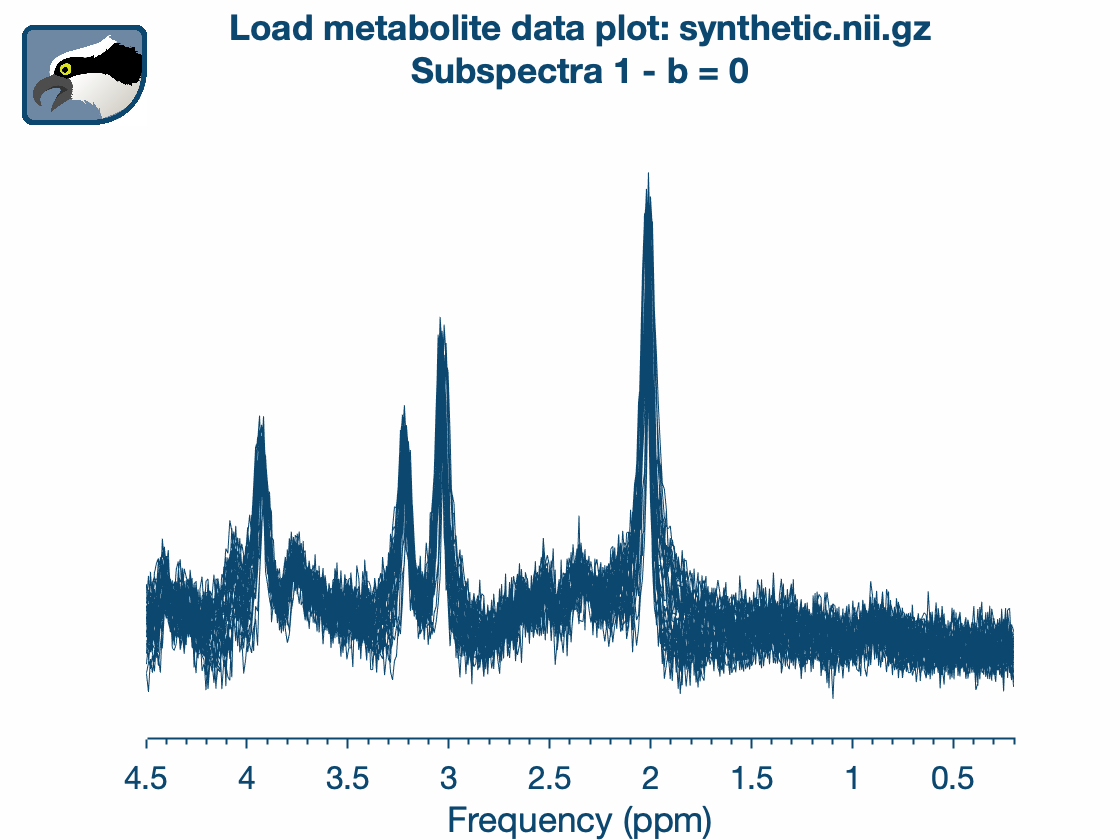

nToShow =1;
osp_plotLoad(dwsynth, 1, 'mets', nToShow);

Each plot is scaled to its own maximum, but as you move the slider across, you can see clearly how the signal-to-noise ratio decreases with increasing diffusion weighting.

## Process data

The next Osprey command, `OspreyProcess`, branches out depending on the type of data that you have provided, and performs a bunch of processing steps, including the alignment of individual transients, weighted averaging, eddy-current-correction (if a water reference signal is available), water removal, pre-phasing and frequency referencing. Let's run it - we'll get back to the individual steps later.

[dwsynth] = OspreyProcess(dwsynth);

Timestamp September 23, 2021 13:30:18 Osprey 1.0.2  OspreyProcess
Processing data from dataset   1 out of   1 total datasets...

... done.
 Elapsed time 46.000529 seconds


This has likely taken a while - after all, we have 9 separate sub-datasets in here, all of which needed to be properly aligned and referenced.

### Visualizing processed data

We can, again, use an Osprey plot function to look at the different processed sub-spectra. The command looks a little different, we have to pass the argument `'A'` to tell Osprey that these are un-spectral-edited data. This overview shows you the individual averages before and after alignment of individual transients, the frequency drift before and after alignment, and the final averaged spectrum in the bottom right corner (again, these are scaled to their individual maxima, but for display purposes only).

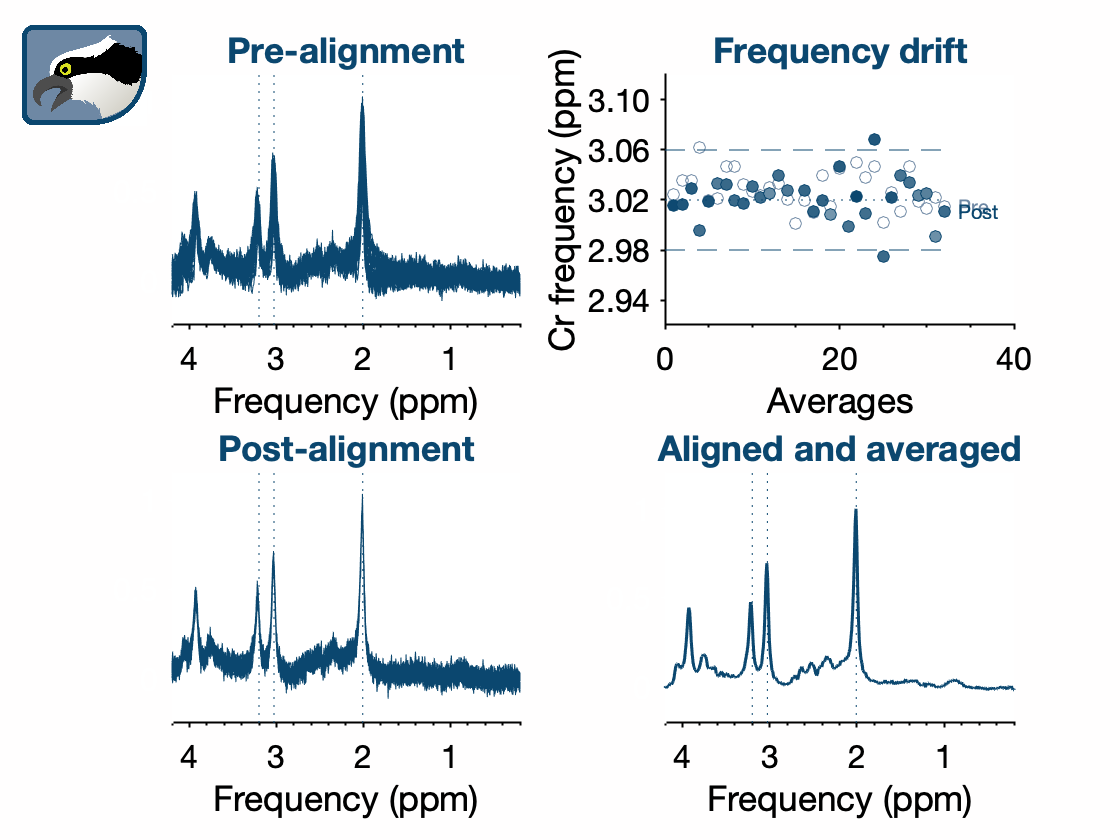

nToShowProc =1;
osp_plotProcess(dwsynth, 1, 'A', nToShowProc);

These are the final spectra that Osprey will pass on to the modeling module in the next step.

## Fit data

The next Osprey command, `OspreyFit`, takes care of the core modeling of the data we have just processed. In this workbook, we are leveraging the built-in LCModel binaries to carry out this task. Osprey only needs a basis set and a template LCModel control file, which we have pointed to in the job file. From there, it carries out all tasks automatically, including writing out the data into the format LCModel requires, setting up the appropriate separate control files for each spectrum that we want to fit, calling the LCModel binary to execute the fit, and read out the LCModel output files to get the results back into the Osprey data container.

[dwsynth] = OspreyFit(dwsynth);

Timestamp September 23, 2021 13:31:06 Osprey 1.0.2  OspreyFit

Fitting metabolite spectra from dataset   1 out of   1 total datasets...

... done.
 Elapsed time 22.808331 seconds


### Visualizing fit data

You guessed it - there is another Osprey function to visualize fit results, `osp_plotFit`. This time, we have to pass the argument `'off'` to tell Osprey that these are un-edited data (Yes, we know - we are working to streamline the terminology!). This shows you the re-imported LCModel fits, including data, model, residuals, baseline estimate, and contributions from each basis function.

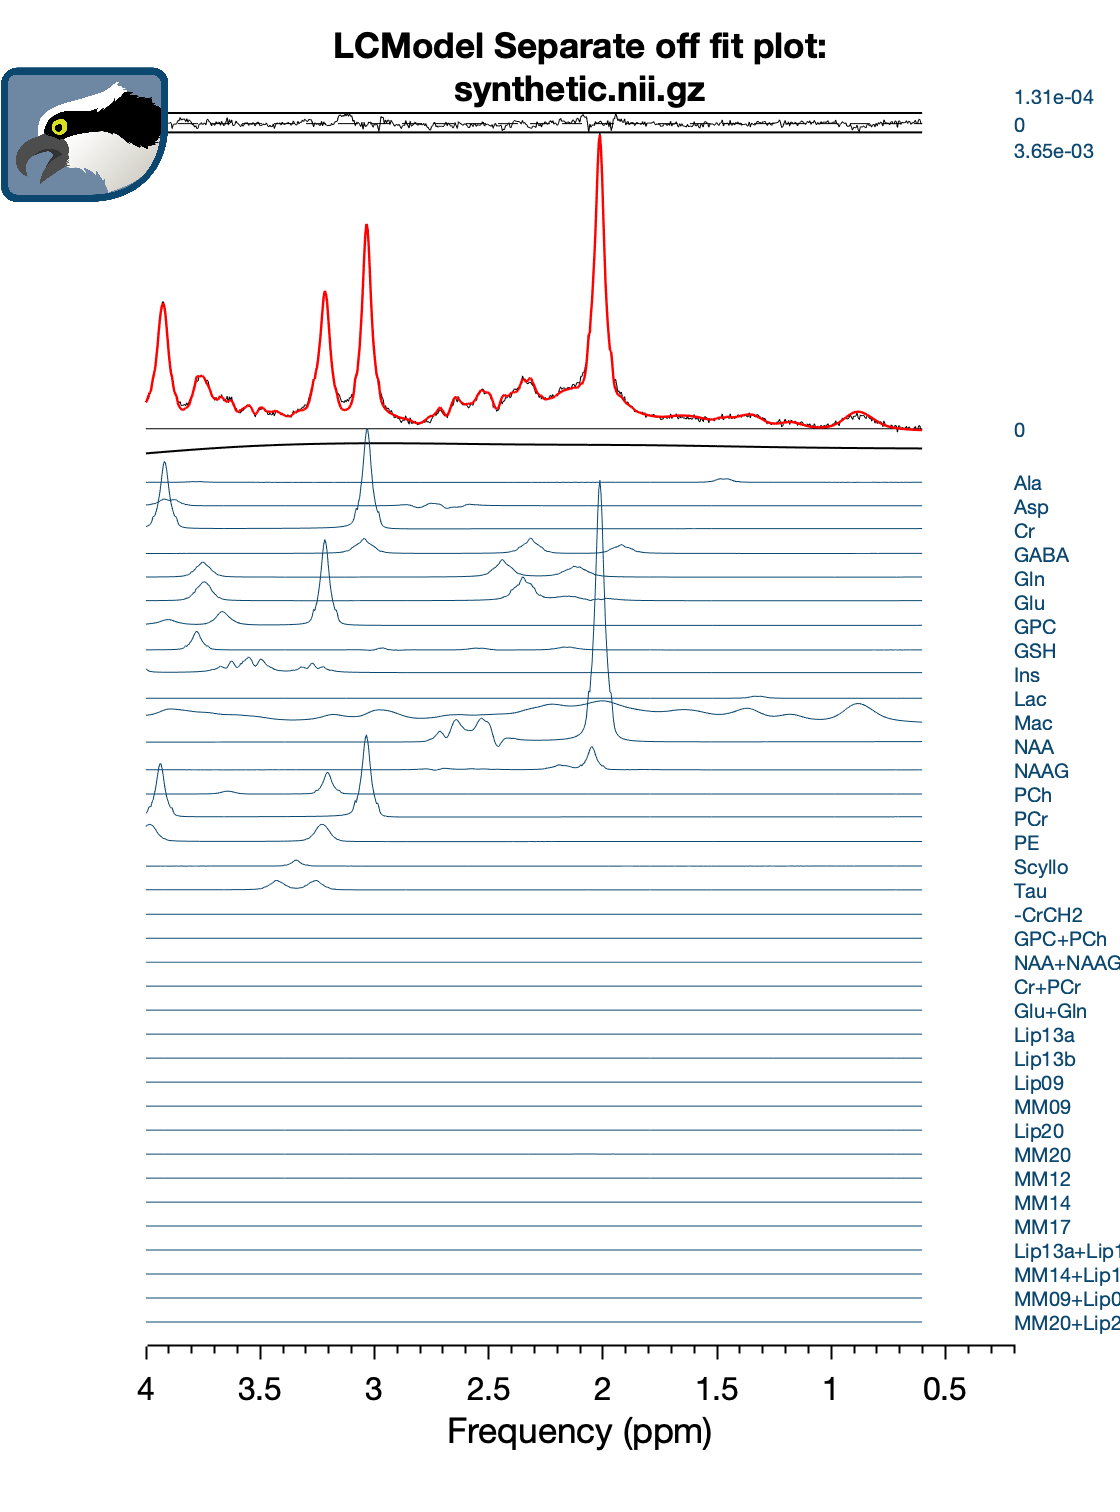

nToShowFit =1;
osp_plotFit(dwsynth, 1, 'off', nToShowFit);

## Packing up the results to report

We now pack up our results to submit them in the format that was requested for the pregame competition:

### Signal decays over b-values

We will now collect the LCModel amplitude results for each metabolite, visualize them, and save them in an exportable file.

% Save the PDFs
outputFolder = fullfile(dwsynth.outputFolder, 'ReportPregame');
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end
% Collect b-values
bVals = dwsynth.raw{1}.nii_mrs.hdr_ext.dim_6_header.Bval;

% Collect amplitudes
names = dwsynth.fit.results.off.fitParams{1}{1}.name;
for rr = 1:length(bVals)
    ampl(:,rr) = dwsynth.fit.results.off.fitParams{1}{rr}.ampl;
    crlb(:,rr) = dwsynth.fit.results.off.fitParams{1}{rr}.CRLB;
end

% Make MATLAB structure
SignalDecay.names       = names;
SignalDecay.amplitudes  = ampl;
SignalDecay.crlb        = crlb;
SignalDecay.bVals       = bVals;

Let's interactively visualize our signal decays so we can decide which ones we think are 'trustworthy'. The error bars here represent the Cramer-Rao lower bounds (CRLB) returned by LCModel, except that they have been converted from relative units (in %) to absolute units.

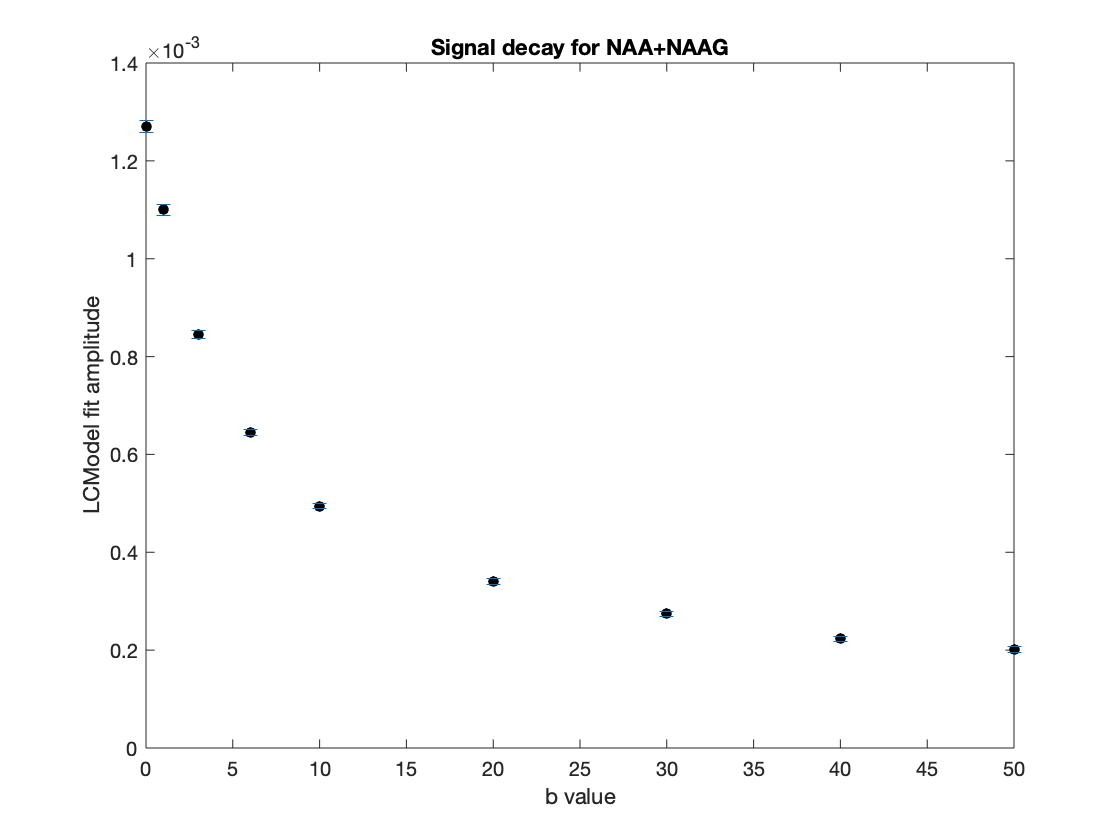

% Visualize
metToPlot = 21;
figure(99);
crlbAbs = SignalDecay.amplitudes .* SignalDecay.crlb .* 0.01;
errorbar(SignalDecay.bVals, SignalDecay.amplitudes(metToPlot, :), crlbAbs(metToPlot, :), 'o', 'MarkerSize', 5, 'MarkerEdgeColor','k', 'MarkerFaceColor', 'k');
xlim([0 Inf]);
xlabel('b value'); ylabel('LCModel fit amplitude'); title(['Signal decay for ' SignalDecay.names{metToPlot}]);

While flipping through the visualization, we have kept track of the signal decays that look reasonably exponential.

We add that to the `SignalDecay` structure, and save on file.

SignalDecay.TrustWorthy = {'Asp', 'Cr', 'GABA', 'Ins', 'NAA', 'PCr', 'PE', 'GPC+PCh', 'NAA+NAAG', 'Glu+Gln', 'Cr+PCr'};
save(fullfile(dwsynth.outputFolder, 'ReportPregame', 'SignalDecay.mat'), 'SignalDecay');

### Difference between ground-truth data and our processed data

First, we were asked to submit the different between the noise-free 'ground-truth' simulated data that was used to create the synthetic dataset, and our processing results of that synthetic dataset. The ground-truth data resides in the file `original.nii.gz`, so we'll import it here:

% Path to original.nii.gz
pathToGroundTruthFile = strrep(dwsynth.files{1}, 'synthetic.nii.gz', 'original.nii.gz');
% Load ground truth data
groundTruth = io_loadspec_niimrs(pathToGroundTruthFile);
% This dataset contains 32 identical averages per b value, so we'll just average them
groundTruth = op_averaging(groundTruth);

% Create an array to hold our processed spectra
specProcessed = zeros(size(groundTruth.specs));
% Collect spectra from each sub-spectrum we processed, and calculate the residual for each b value
for rr = 1:9
    specProcessed(:,rr) = dwsynth.processed.A{1}{rr}.specs;
end

% Compute difference
DiffProcessedVersusGroundTruth = groundTruth.specs - specProcessed;
save(fullfile(dwsynth.outputFolder, 'ReportPregame', 'GroundTruthComparison.mat'), 'DiffProcessedVersusGroundTruth');

We can now interactively visualize the differences:

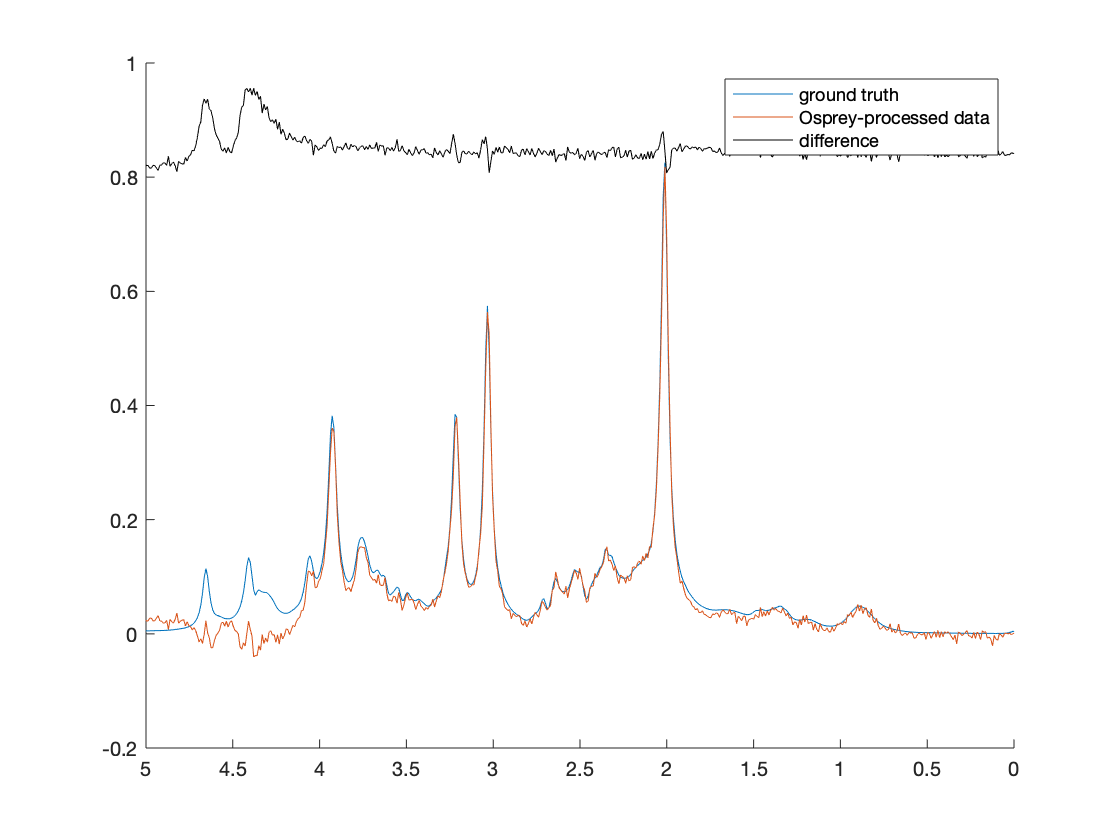

nToShowGroundTruth = 2;
figure;
hold on;
plot(groundTruth.ppm, real(groundTruth.specs(:,nToShowGroundTruth)));
plot(groundTruth.ppm, real(specProcessed(:,nToShowGroundTruth)));
plot(groundTruth.ppm, real(DiffProcessedVersusGroundTruth(:,nToShowGroundTruth)) + max(abs(groundTruth.specs(:,nToShowGroundTruth))), 'k');
hold off;
set(gca, 'xdir', 'reverse', 'xlim', [0 5]);
legend('ground truth', 'Osprey-processed data', 'difference');

### Visualizations of modeling residuals

Next, we'll create a visualization of our modeling results - let's simply save each of the OspreyFit output plots (with the file names indicating the b values).

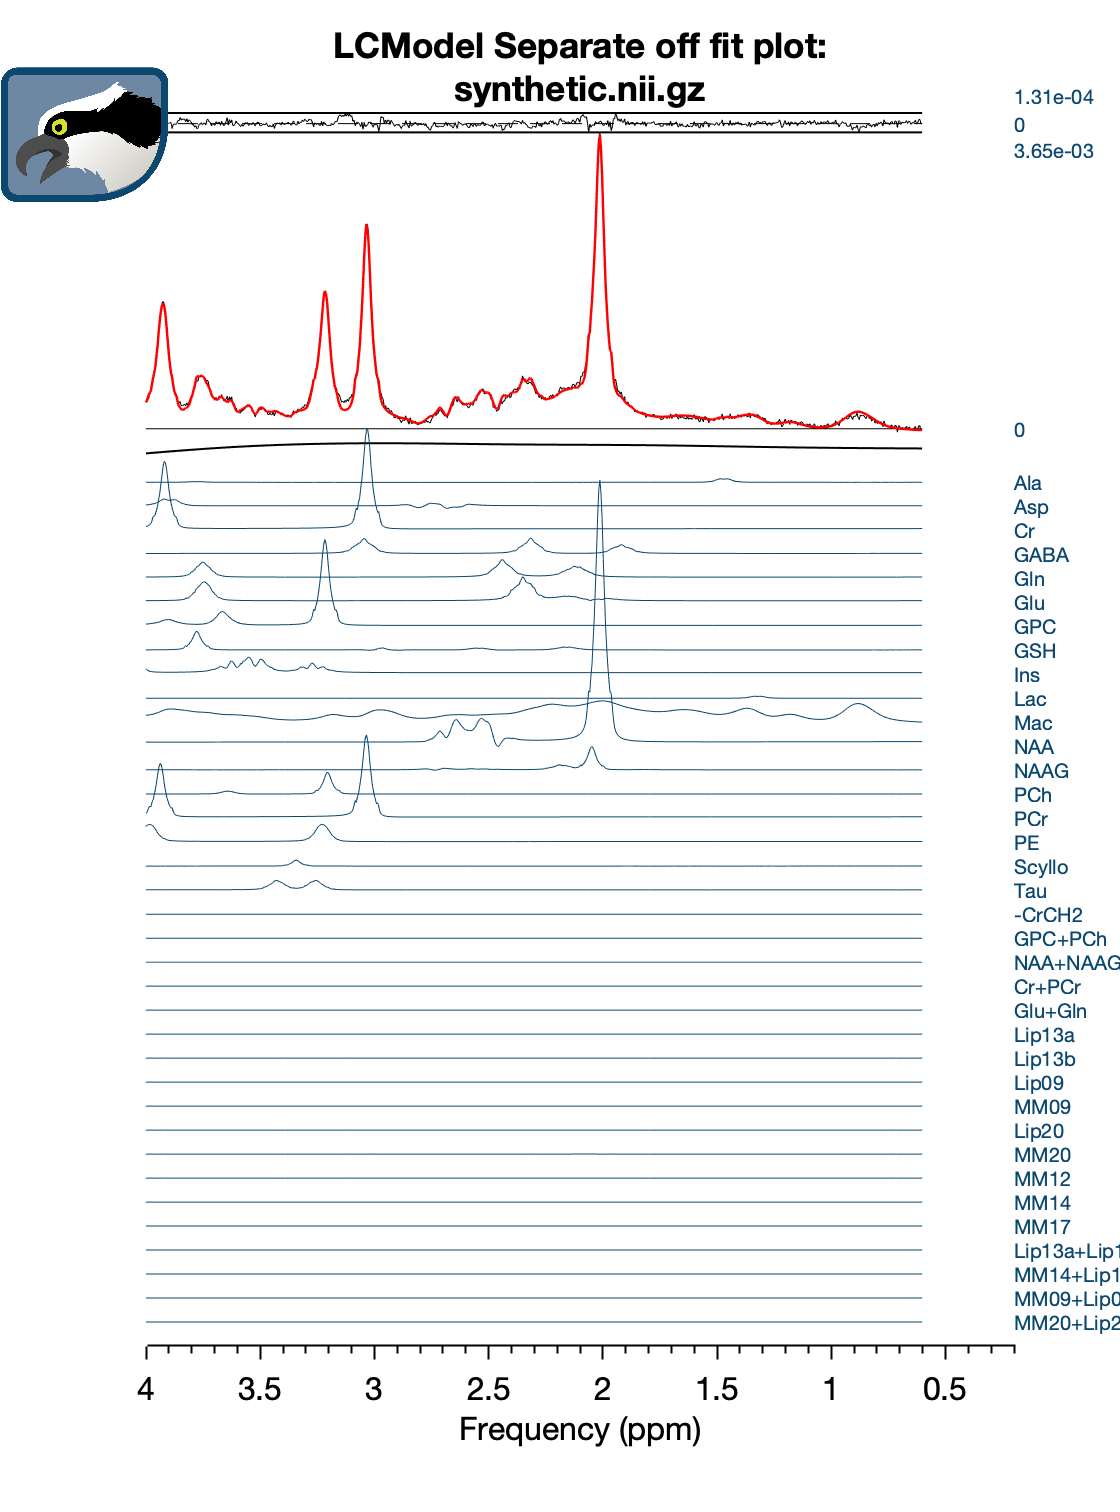

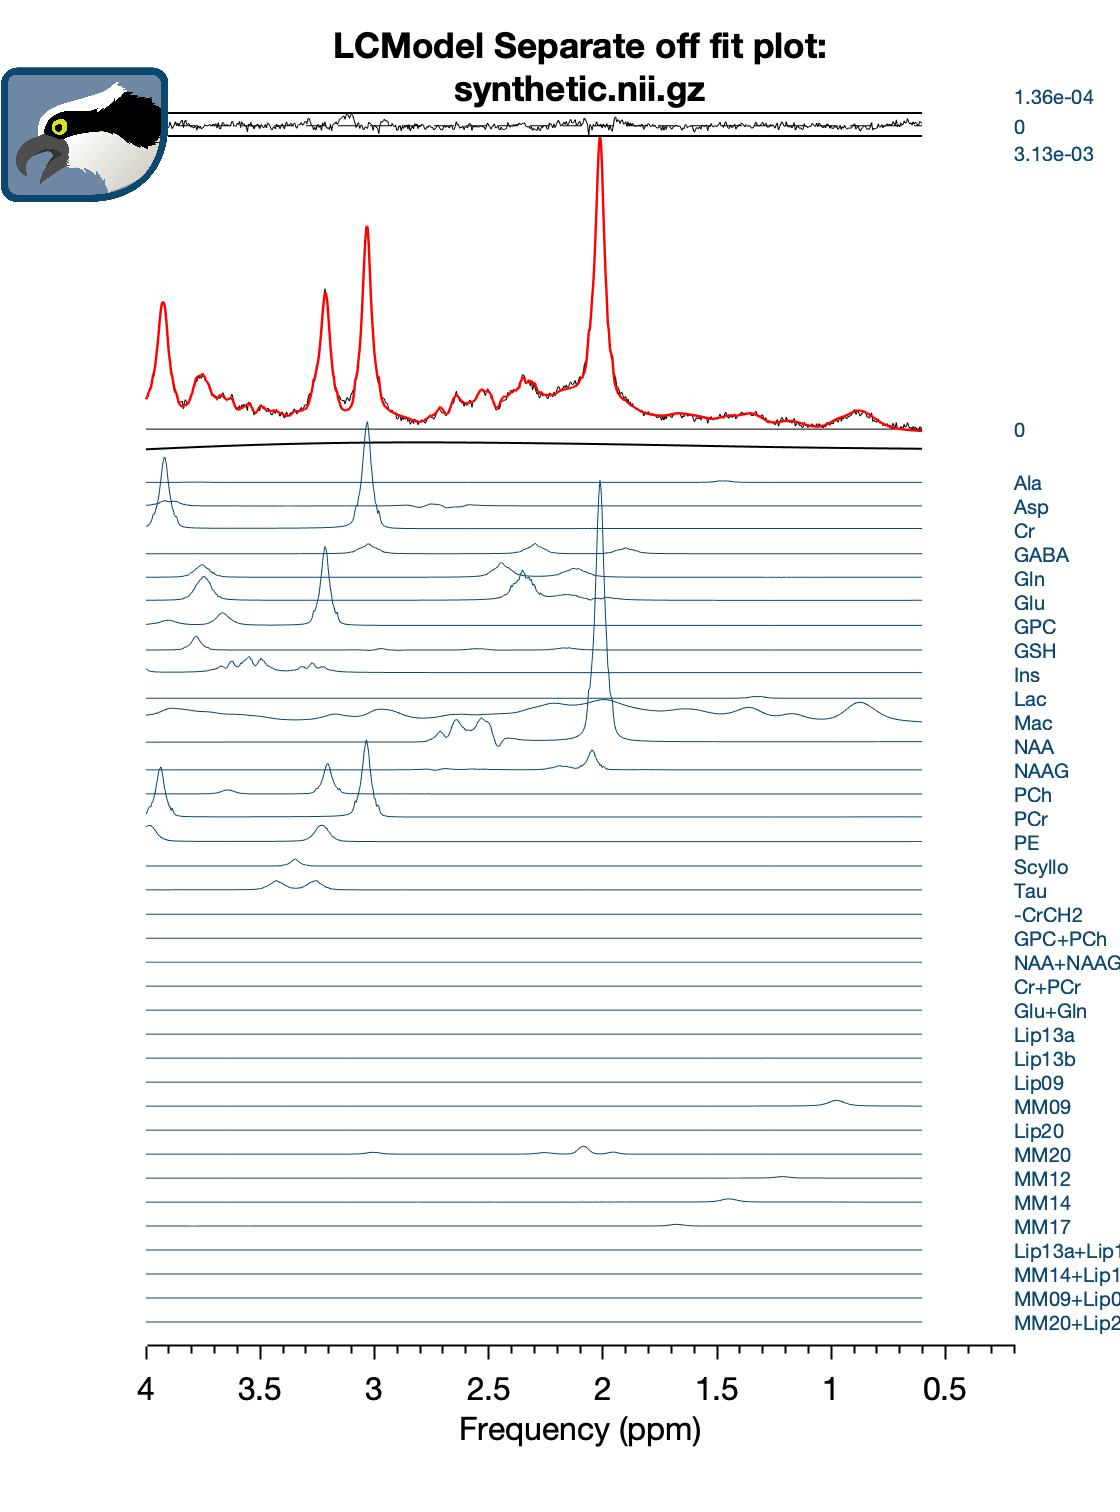

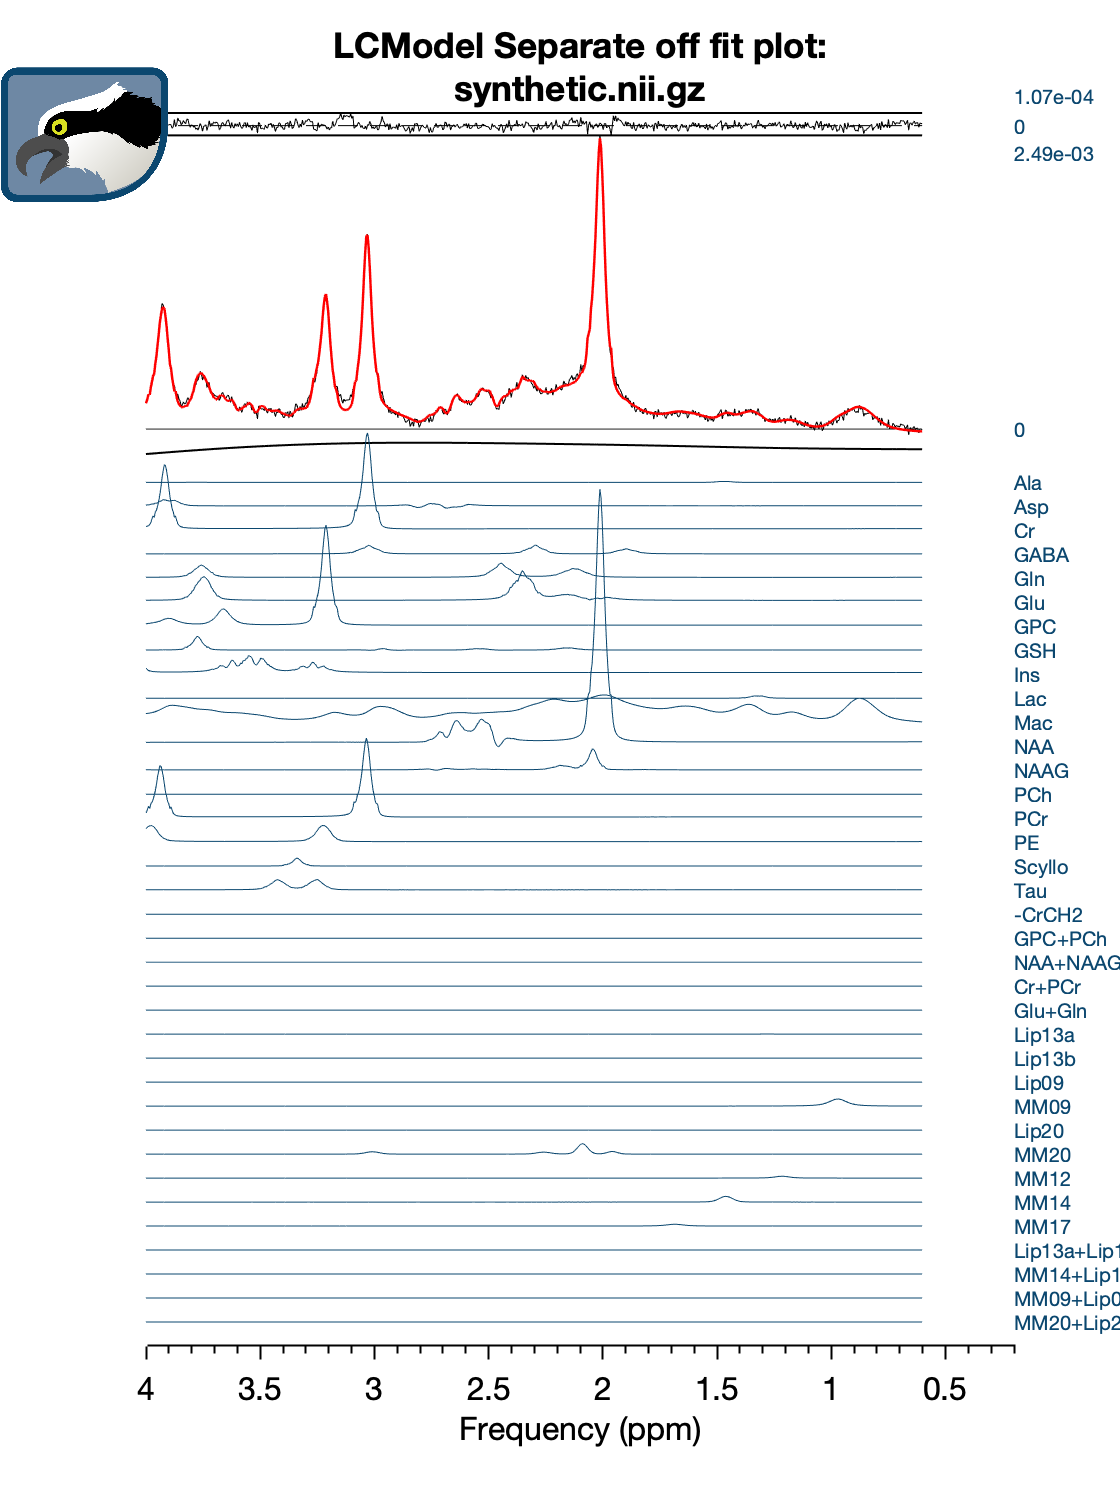

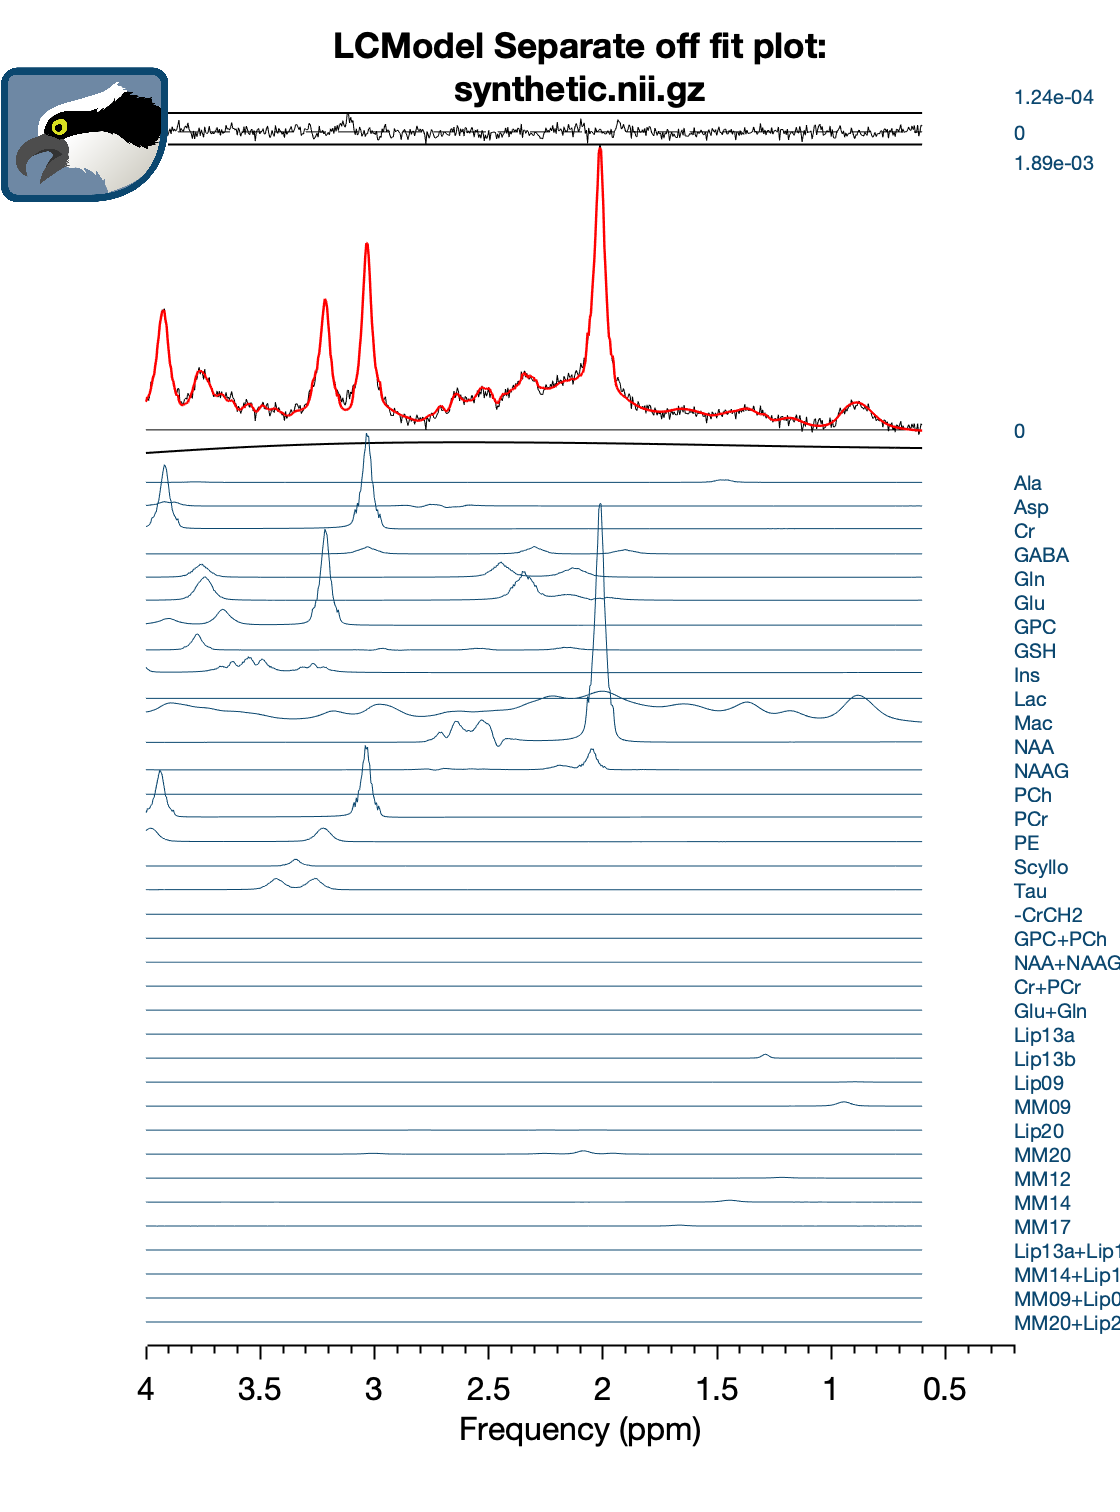

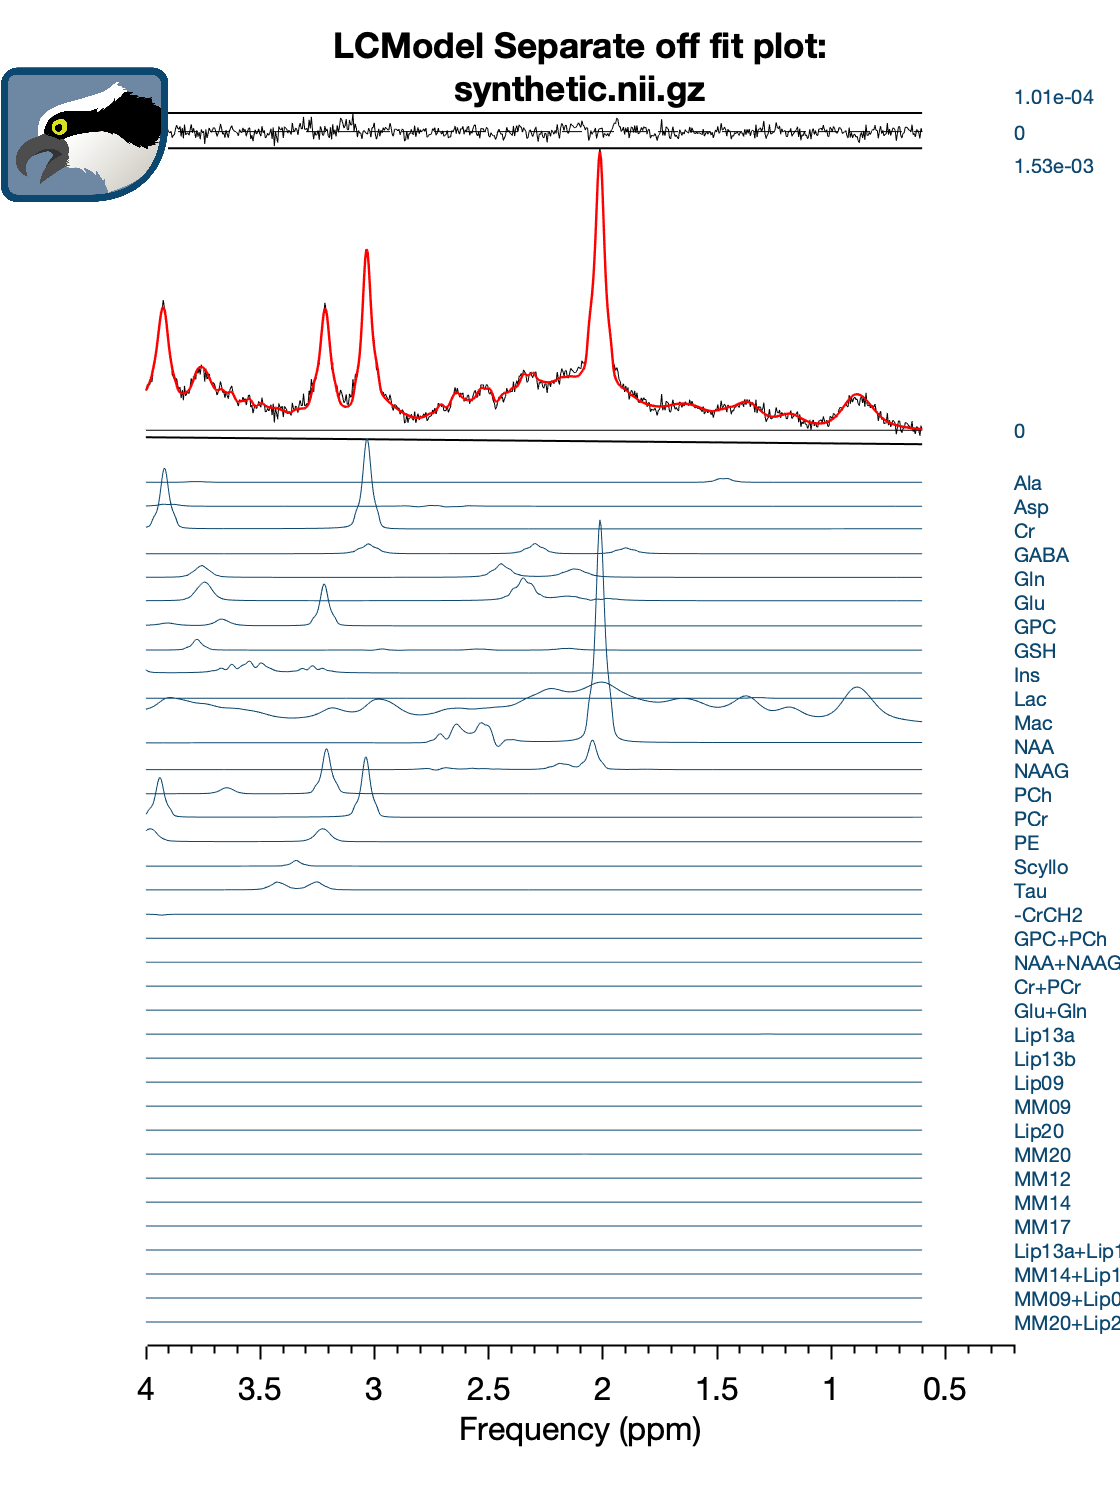

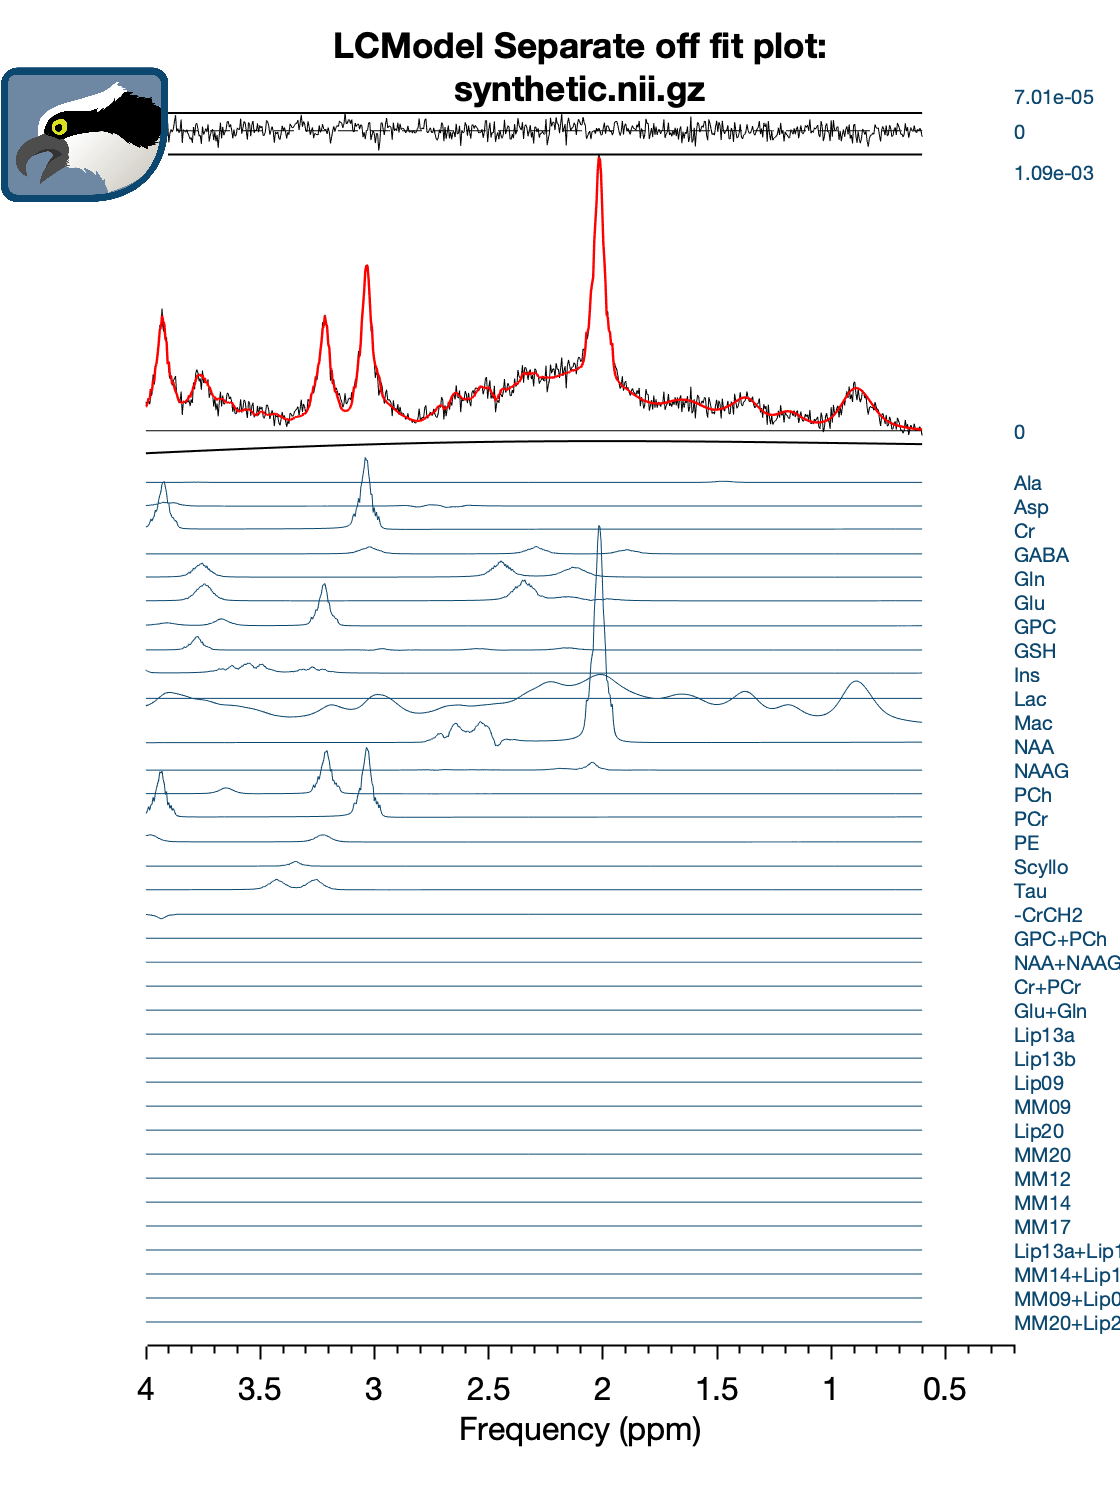

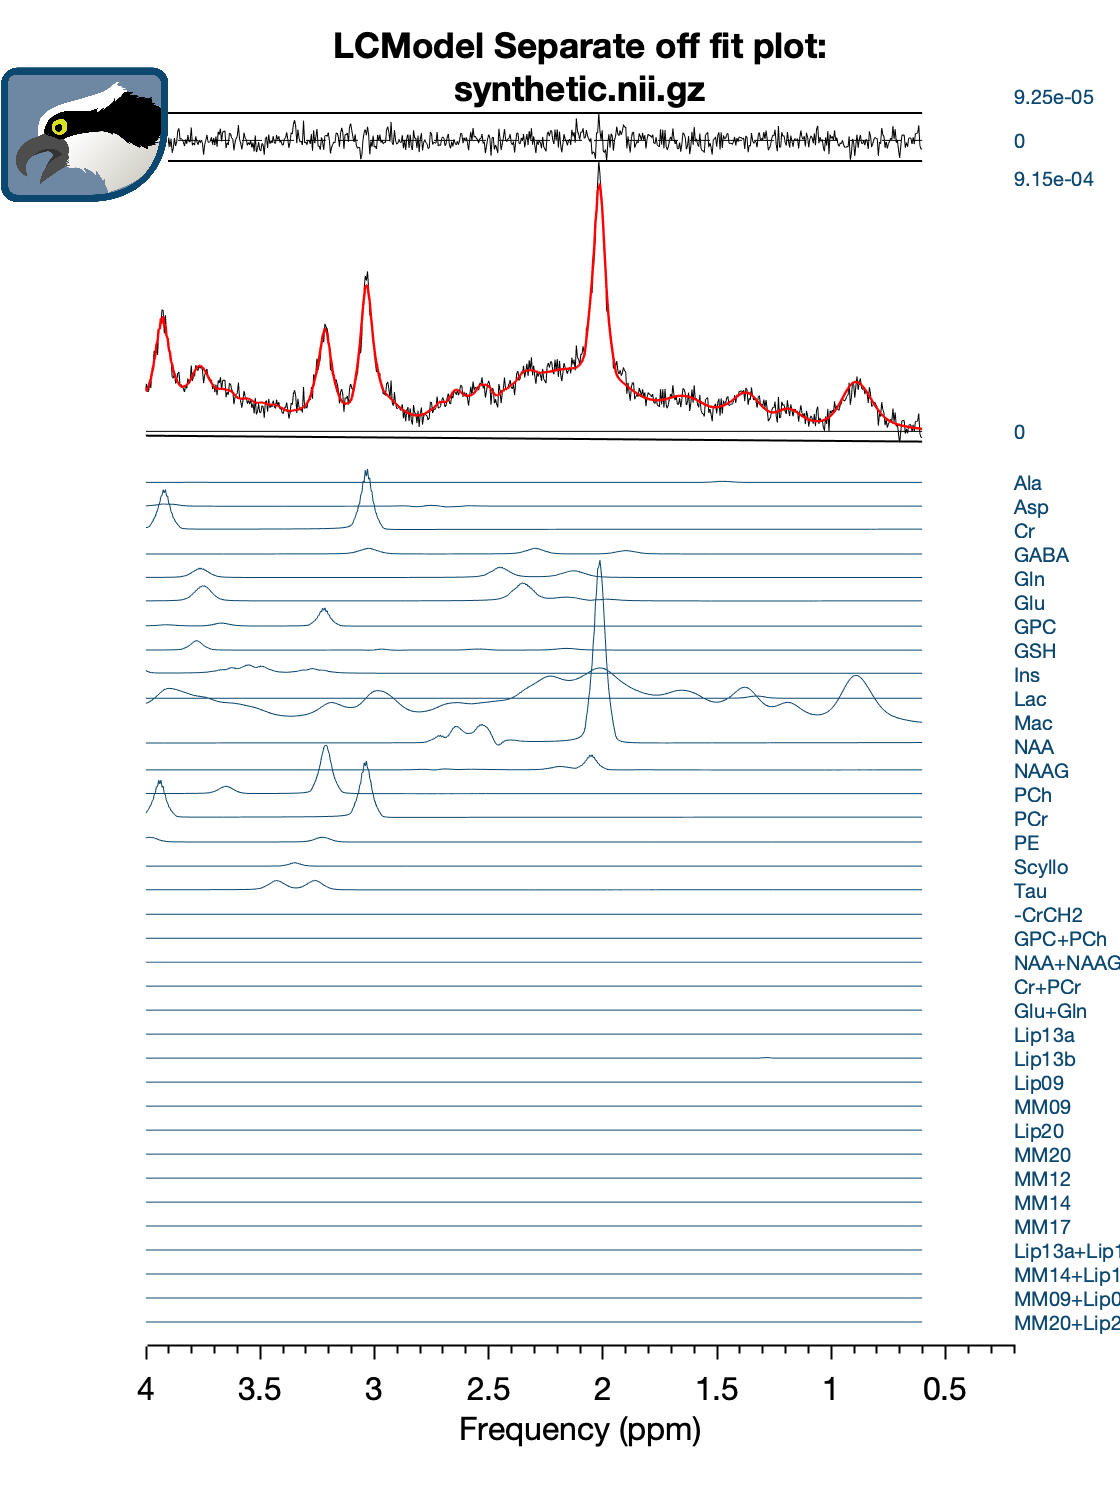

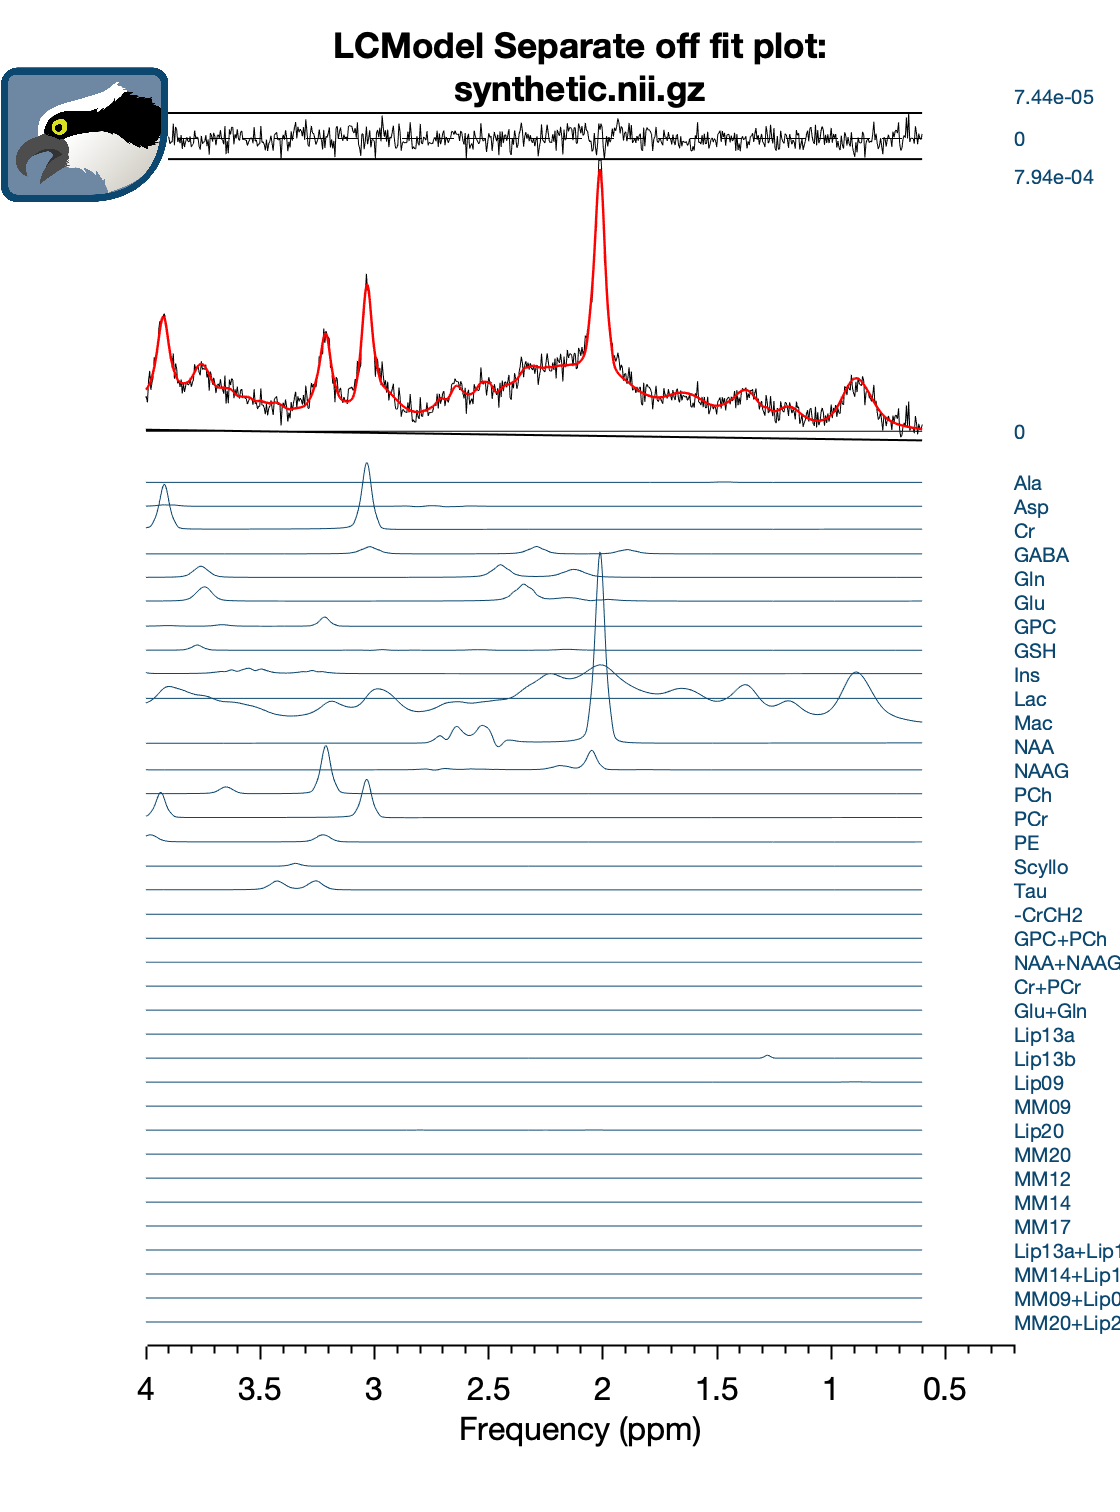

% Save the PDFs
outputFolder = fullfile(dwsynth.outputFolder, 'ReportPregame', 'Figures', 'OspreyFit');
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end
bVals = dwsynth.raw{1}.nii_mrs.hdr_ext.dim_6_header.Bval;
for rr = 1:9
    fig = osp_plotFit(dwsynth, 1, 'off', rr);
    outputFileName = ['OspreyFit_bVal_' num2str(bVals(rr))];
    saveas(fig,fullfile(outputFolder, outputFileName),'pdf');
    close(fig);
end